clear; % Limpiar todas las variables almacenadas en la memoria
close all; % Cerrar todas las figuras que puedan estar abiertas
clc; % Limpiar la ventana de comandos
%Datos de prueba de entrada
In=[2.5 2.5  2.5  -10  10 5  5  5  5  1   1   1  1   -3  -3  -3  -3   -8  -8  -8  -8];

ni_In=0;    %instante inicio
l_In=length(In);              %longitud vector In
nf_In=l_In+ni_In-1;


%Prueba Funcion
Out=normalizeSignal(In,1)

Out =     0.6250    0.6250    0.6250         0    1.0000    0.7500    0.7500    0.7500    0.7500    0.5500    0.5500    0.5500    0.5500    0.3500    0.3500    0.3500    0.3500    0.1000    0.1000    0.1000    0.1000


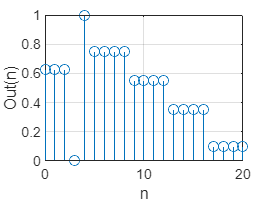

%Grafica de datos normalizados
n=ni_In:nf_In;
stem(n,Out); xlabel('n');ylabel('Out(n)');grid on;

function [normalizedSignal] = normalizeSignal(signal, normalizationType)
    % Función para normalizar la señal discreta
    % Entradas:
    % signal: Vector de la señal discreta
    % normalizationType: Tipo de normalización
    %   1 - Normalización entre 0 y 1
    %   2 - Normalización entre -1 y 1
    %   3 - Normalización estándar (media cero y desviación estándar unitaria)
    %
    % Salidas:
    % normalizedSignal: Vector de la señal normalizada
    
    % Validación del tipo de normalización
    if normalizationType < 1 || normalizationType > 3
        error('Tipo de normalización no válido. Debe ser 1, 2 o 3.');
    end

    switch normalizationType
        case 1  % Normalización entre 0 y 1
            minVal = min(signal);
            maxVal = max(signal);
            normalizedSignal = (signal - minVal) / (maxVal - minVal);
        
        case 2  % Normalización entre -1 y 1
            maxAbsVal = max(abs(signal));
            normalizedSignal = signal / maxAbsVal;

        case 3  % Normalización estándar (media cero y desviación estándar unitaria)
            meanSignal = mean(signal);
            stdSignal = std(signal);
            normalizedSignal = (signal - meanSignal) / stdSignal;
    end
end